# First Part - 1 dof sin-sweep input

close all; clear all; clc;

As first passage we load and extract the necessary data:

load('data_1dof_sine_sweep.mat');
input_signal = data(:,1)*0.01;      % [V]
time = data(:,2);                   % [s]
output_signal = data(:,3)*0.01;     % [m]

Input sequence is a voltage and the output is the position recorded by the encoder.

## 1.1 Sampling Freqency

We need to find the sampling frequency of the encoder:

number_of_samples = size(data,1);
total_time = max(time);

fs = number_of_samples/total_time;  %[Hz]
disp(['The sampling frequency of the encoder is: ' num2str(fs) ' Hz']);

The sampling frequency of the encoder is: 1000.011 Hz


We can observe the plot of the input voltage signal and the output position signal:

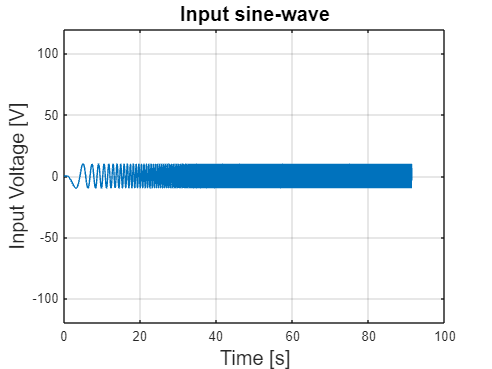

figure(1)
plot(time, input_signal)
xlabel('Time [s]','FontSize',15)
ylabel('Input Voltage [V]','FontSize',15)
title('Input sine-wave','FontSize',15)
axis([0 100 -120 120])
grid on

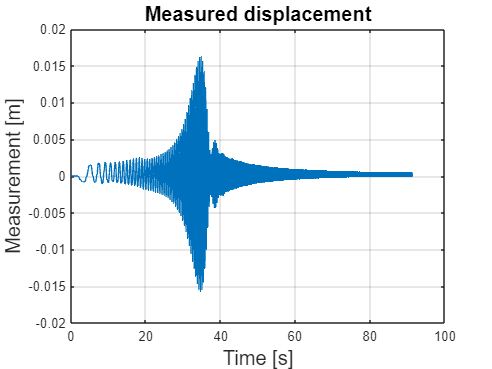


figure(2)
plot(time, output_signal, 'LineWidth',1)
xlabel('Time [s]','FontSize',15)
ylabel('Measurement [m]','FontSize',15)
title('Measured displacement','FontSize',15)
grid on

## 1.2 Experimental Transfer Function

Now we estimate the Transfer Function between the cart position and the voltage (which are respectly the output and the input):

[Tf,Fr] = tfestimate(input_signal,output_signal,[],[],[],fs);

Tm = abs(Tf);
Tm_phase = unwrap(angle(Tf));

Where:

    - **Tf** is the vector representing the estimated complex **Transfer Function**

    - **Fr** is the vector representing the **Frequencies**

    - **Tm** is the vector representing the **Magnitude** of the tf

    - **Tm_phase** is the vector representing the **Phase** of the tf

We can take a look to the plots of the magnitude and the phase of the transfer function:

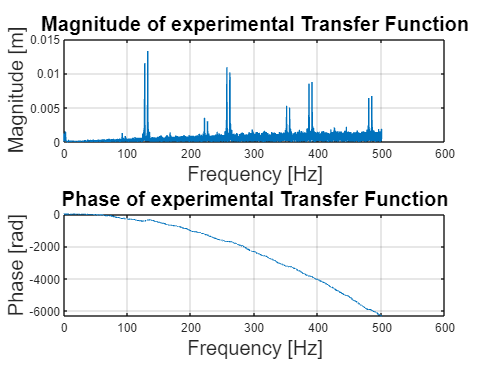

figure;
subplot(2,1,1);
plot(Fr, Tm);
xlabel('Frequency [Hz]','FontSize',15);
ylabel('Magnitude [m]','FontSize',15);
title('Magnitude of experimental Transfer Function','FontSize',15);
grid on;

subplot(2,1,2);
plot(Fr, Tm_phase);
xlabel('Frequency [Hz]','FontSize',15);
ylabel('Phase [rad]','FontSize',15);
title('Phase of experimental Transfer Function','FontSize',15);
grid on

We can clearly see the plot is overcrowded, we expect the natural frequency to have a small value, so for example we can consider to truncate the data to the first 200 samples in frequency domain:

L = 200;                            % truncation
Tf_1 = Tf(1:L);                     % [m]
Fr_1 = Fr(1:L);                     % [Hz]
Tm_1 = abs(Tf_1);                   % [m]
Tm_phase_1 = unwrap(angle(Tf_1));   % [Hz]

And we can take a look to the plots of the cleared output:

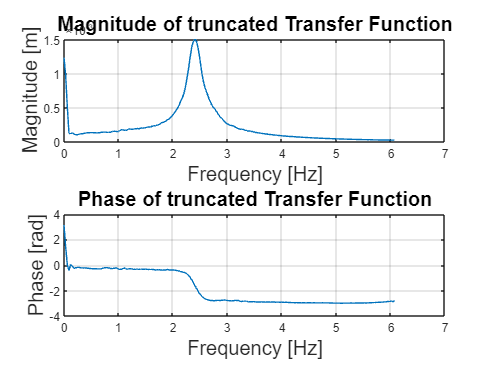

figure, clf
subplot(2,1,1)
plot(Fr_1, Tm_1)
xlabel('Frequency [Hz]','FontSize',15);
ylabel('Magnitude [m]','FontSize',15);
title('Magnitude of truncated Transfer Function','FontSize',15);
grid on

subplot(2,1,2)
plot(Fr_1, Tm_phase_1);
xlabel('Frequency [Hz]','FontSize',15);
ylabel('Phase [rad]','FontSize',15);
title('Phase of truncated Transfer Function','FontSize',15);
grid on

The peak of the **natural frequency** is now clear.

## 1.3 Half Power Point Method

Now we can use the suggested *Half Power Point Method* in order to estimate the damping ratio of the natural frequency.

First we estimate the peak of the transfer function and divide by the square root of 2 to have the *effective power.*

Q = max(Tm_1);  % peak value
g = Q/sqrt(2);  % half power

Define the random starting point and solve as suggested:

x1 = [2.25833 0.00093];
x2 = [2.53299 0.00101];

sol1 = fsolve(@(x)interp1(Fr_1, Tm_1, x, 'spline') - g, x1);


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


sol2 = fsolve(@(x)interp1(Fr_1, Tm_1, x, 'spline') - g, x2);


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



omega1 = sol1(1)

omega1 = 2.2583

omega2 = sol2(1)

omega2 = 2.5330

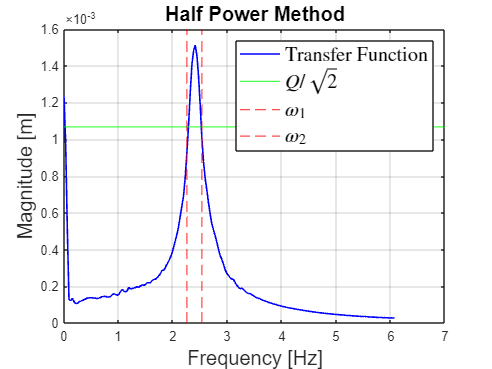


figure, clf
plot(Fr_1, Tm_1,'b','LineWidth',1.2)
yline(g,'g','LineWidth',0.9)
xline(omega1,'r--','LineWidth',1.0)
xline(omega2,'r--','LineWidth',1.0)
xlabel("Frequency [Hz]",'FontSize',15)
ylabel("Magnitude [m]",'FontSize',15)
title('Half Power Method','FontSize',15)
legend('Transfer Function','$$Q/\sqrt2$$', '$$\omega_1$$', '$$\omega_2$$','Interpreter','Latex','FontSize',15)
grid on

As last passage we can compute the damping ratio of the natural frequency:

omega_n1 = (omega1 + omega2)/2;
damping1 = (omega2-omega1)/(omega2+omega1);

disp(['The natural frequency is: ' num2str(omega_n1) ' rad/s']);

The natural frequency is: 2.3957 rad/s


disp(['The damping ratio is: ' num2str(damping1)]);

The damping ratio is: 0.057324
